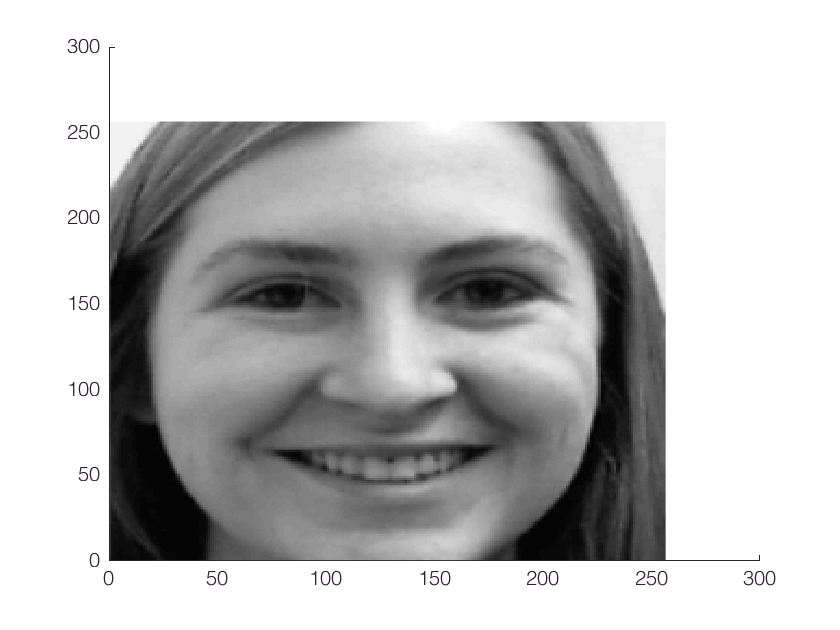

load face_detect.mat

%number of images in eigenfaces
num = 40;

%vectorize the images
vectorizedImages = reshape(faces_test_easy, [size(faces_test_easy, 1) * size(faces_test_easy, 2)], size(faces_test_easy, 3));

%creating a covariance matrix
o = ones(size(vectorizedImages, 1), 1);
m = o * mean(vectorizedImages);
covariance = 1/sqrt((size(vectorizedImages, 1)))*(vectorizedImages - m);

%finding the eigenvectors using SVD
[U, S, V] = svd(covariance, 'econ');
eigenvalues = diag(S);
lambda = eigenvalues(1:num);
v = U(:, 1:num);

%project the images
features = v' * (vectorizedImages - m);

%for i = 1:size(faces_train, 3)
   featureVector = v' * (vectorizedImages(:,20) - mean(vectorizedImages, 2));
   simScore = arrayfun(@(n) 1 / (1 + norm(features(:,n) - featureVector)), 1:40);
   [score, index] = max(simScore);
%end

figure;
hold on;
image1 = imrotate(faces_train(:,:,20), 180);
imagesc(image1); colormap('gray');
hold off;

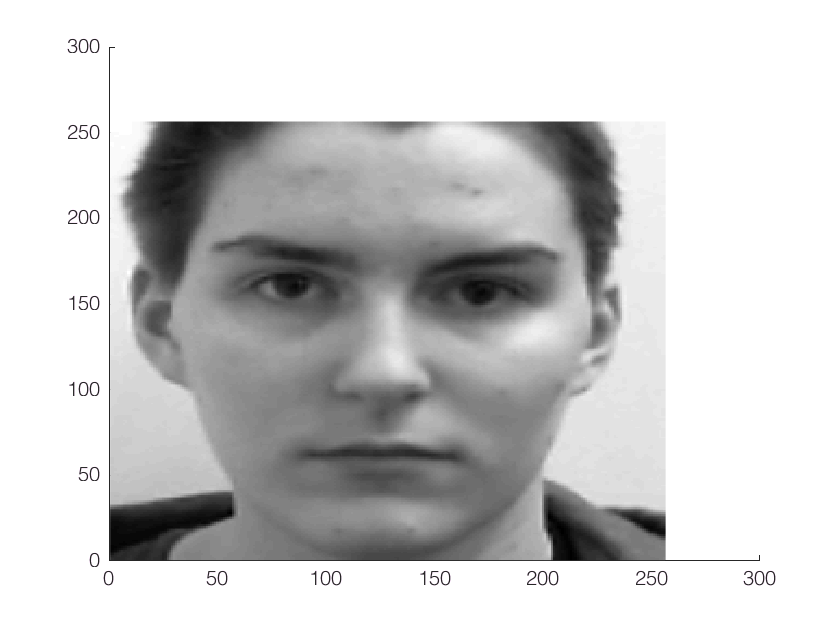

figure;
hold on;
image2 = imrotate(faces_test_easy(:,:,index), 180);
imagesc(image2); colormap('gray');
hold off;